addpath("D:\Documents\bags")


%Extracting data from rosbag
bag =  rosbag("same_position.bag")

bag =   BagSelection with properties:

           FilePath: 'D:\Documents\bags\same_position.bag'
          StartTime: 1.4970e+09
            EndTime: 1.4970e+09
        NumMessages: 13457
    AvailableTopics: [2×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [13457×4 table]


bag2 = rosbag("reading2.bag")

bag2 =   BagSelection with properties:

           FilePath: 'D:\Documents\bags\reading2.bag'
          StartTime: 1.6505e+09
            EndTime: 1.6505e+09
        NumMessages: 169571
    AvailableTopics: [6×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [169571×4 table]



imu_bag = select(bag, 'Topic', '/imu/data')

imu_bag =   BagSelection with properties:

           FilePath: 'D:\Documents\bags\same_position.bag'
          StartTime: 1.4970e+09
            EndTime: 1.4970e+09
        NumMessages: 11902
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [11902×4 table]


imu_bag2 = select(bag2, 'Topic', '/imu/imu')

imu_bag2 =   BagSelection with properties:

           FilePath: 'D:\Documents\bags\reading2.bag'
          StartTime: 1.6505e+09
            EndTime: 1.6505e+09
        NumMessages: 73465
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [73465×4 table]


msgs = readMessages(imu_bag,"DataFormat","struct");
msgs2 = readMessages(imu_bag2,"DataFormat","struct");

ans = struct with fields:
                     MessageType: 'sensor_msgs/Imu'
                          Header: [1×1 struct]
                     Orientation: [1×1 struct]
           OrientationCovariance: [9×1 double]
                 AngularVelocity: [1×1 struct]
       AngularVelocityCovariance: [9×1 double]
              LinearAcceleration: [1×1 struct]
    LinearAccelerationCovariance: [9×1 double]


ans = struct with fields:
                     MessageType: 'sensor_msgs/Imu'
                          Header: [1×1 struct]
                     Orientation: [1×1 struct]
           OrientationCovariance: [9×1 double]
                 AngularVelocity: [1×1 struct]
       AngularVelocityCovariance: [9×1 double]
              LinearAcceleration: [1×1 struct]
    LinearAccelerationCovariance: [9×1 double]



%Linear Acceleration
acc_x =  cellfun(@(m) double(m.LinearAcceleration.X),msgs)

acc_x =     0.0348
   -0.0827
   -0.1768
   -0.1998
    0.1509
    0.4315
    0.6862
    0.9110
    1.0908
    1.0972


acc_y =  cellfun(@(m) double(m.LinearAcceleration.Y),msgs)

acc_y =     0.2660
    0.4528
    0.6022
    0.5743
    0.4753
    0.3961
    0.5023
    0.2564
    0.0596
   -0.1155


acc_z =  cellfun(@(m) double(m.LinearAcceleration.Z),msgs)

acc_z =     9.0547
    9.9909
   10.7399
   10.9253
   10.3554
    9.8995
    9.9816
   10.3488
   10.6427
   10.5722



acc_x2 =  cellfun(@(m) double(m.LinearAcceleration.X),msgs2)

acc_x2 =    -0.3143
   -0.5840
   -0.5739
   -0.2605
   -0.0004
    0.0596
   -0.0044
   -0.1380
   -0.2353
   -0.1733


acc_y2 =  cellfun(@(m) double(m.LinearAcceleration.Y),msgs2)

acc_y2 =    -0.3156
   -0.6680
   -0.9085
   -0.9236
   -0.9615
   -0.9716
   -1.1829
   -1.0153
   -0.8642
   -0.8063


acc_z2 =  cellfun(@(m) double(m.LinearAcceleration.Z),msgs2)

acc_z2 =    -9.5374
   -9.6208
   -9.8426
  -10.0426
   -9.8371
   -9.7582
   -9.7829
   -9.9465
   -9.7113
   -9.5990


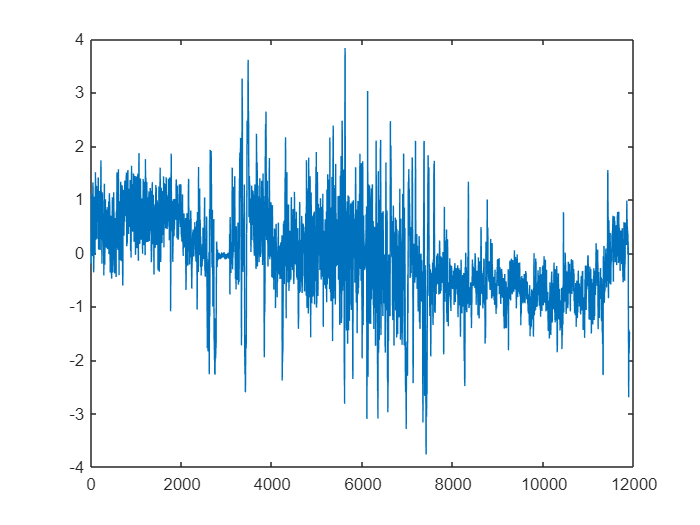


plot(acc_x)

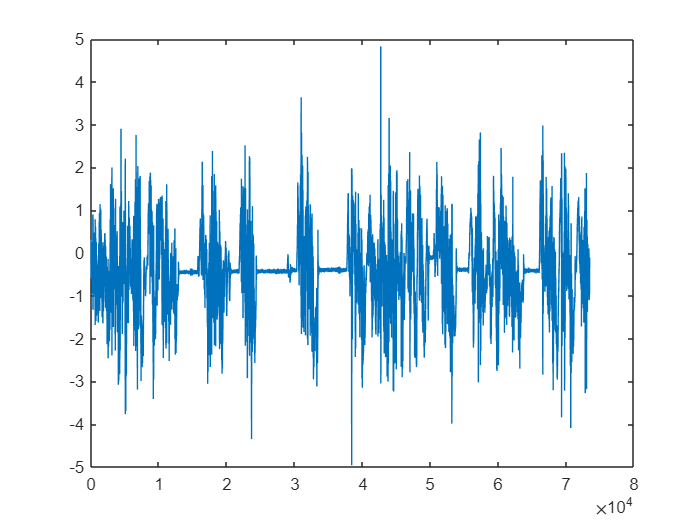

plot(acc_x2)

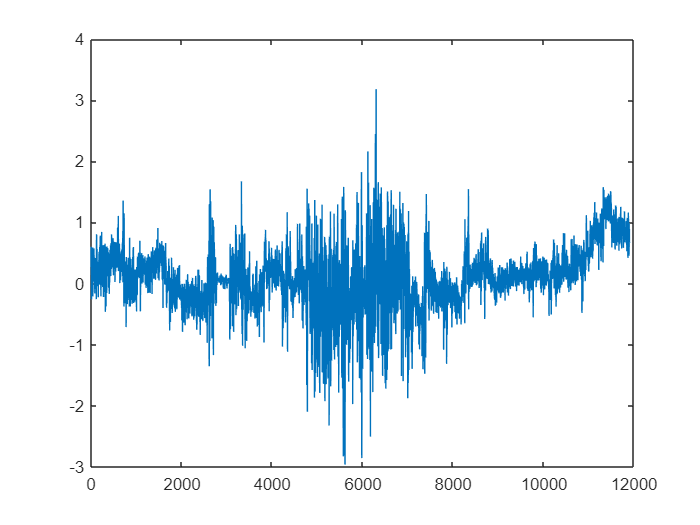


plot(acc_y)

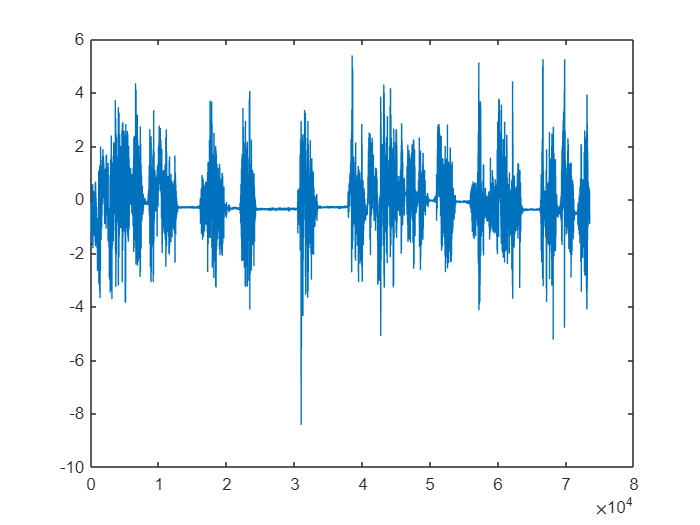

plot(acc_y2)

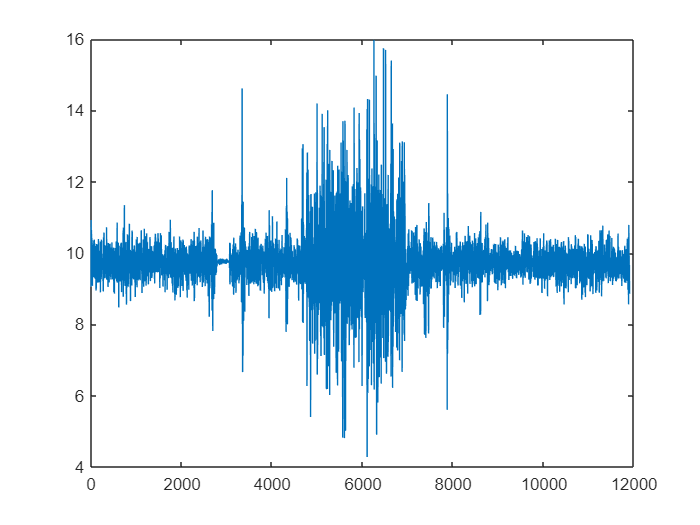


plot(acc_z)

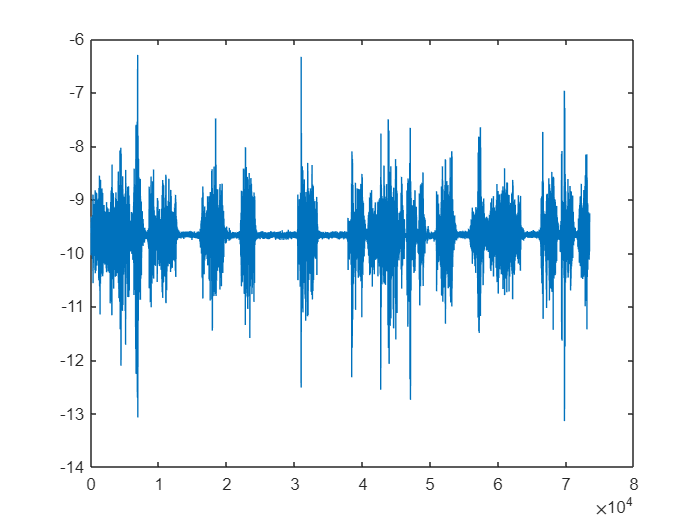

plot(acc_z2)



%Angular Velocity
avel_x =  cellfun(@(m) double(m.AngularVelocity.X),msgs)

avel_x =     0.0088
    0.0201
    0.0292
    0.0152
    0.0202
    0.0243
    0.0072
    0.0048
    0.0029
    0.0059


avel_y =  cellfun(@(m) double(m.AngularVelocity.Y),msgs)

avel_y =    -0.0189
   -0.0208
   -0.0223
   -0.0197
   -0.0170
   -0.0148
   -0.0178
   -0.0034
    0.0082
    0.0130


avel_z =  cellfun(@(m) double(m.AngularVelocity.Z),msgs)

avel_z =     0.0190
    0.0157
    0.0130
    0.0139
    0.0170
    0.0195
    0.0155
    0.0091
    0.0039
    0.0085



avel_x2 =  cellfun(@(m) double(m.AngularVelocity.X),msgs2)

avel_x2 =     0.0198
    0.0165
    0.0180
    0.0164
    0.0128
    0.0090
    0.0051
    0.0047
    0.0000
   -0.0001


avel_y2 =  cellfun(@(m) double(m.AngularVelocity.Y),msgs2)

avel_y2 =    -0.0471
   -0.0164
    0.0167
    0.0300
    0.0195
   -0.0023
   -0.0214
   -0.0156
   -0.0060
    0.0154


avel_z2 =  cellfun(@(m) double(m.AngularVelocity.Z),msgs2)

avel_z2 =    -0.0791
   -0.0788
   -0.0753
   -0.0752
   -0.0751
   -0.0762
   -0.0756
   -0.0747
   -0.0745
   -0.0727


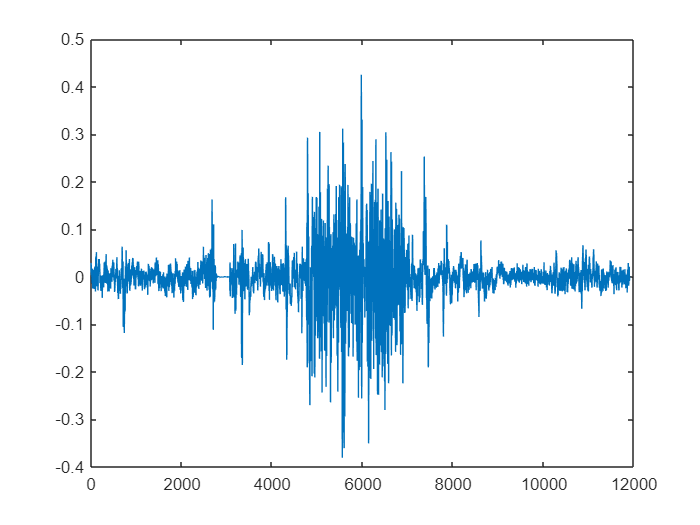


plot(avel_x)

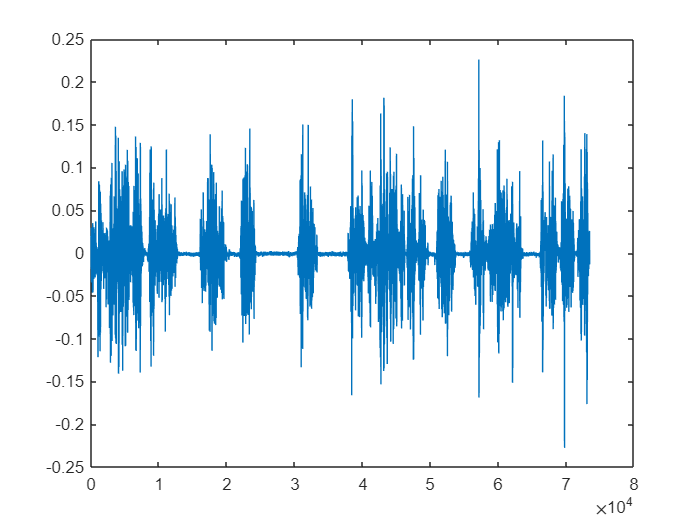

plot(avel_x2)

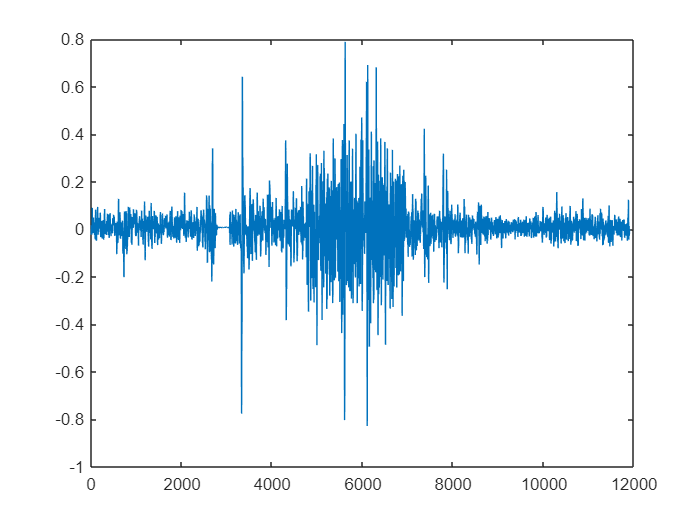


plot(avel_y)

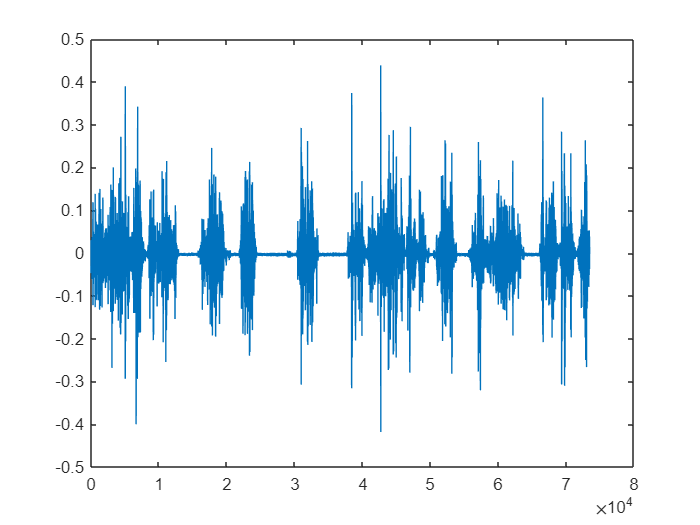

plot(avel_y2)

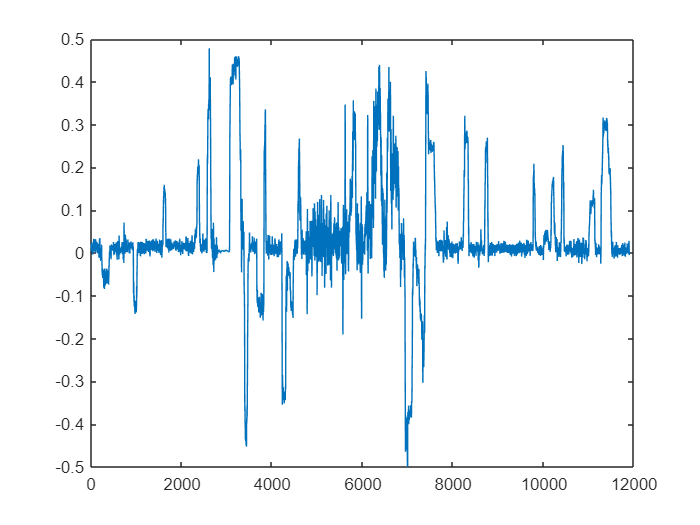


plot(avel_z)

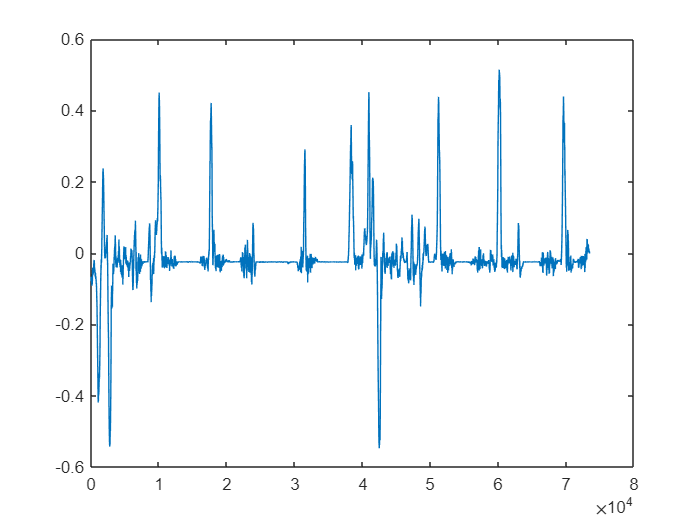

plot(avel_z2)